N = 200;          %粒子链总长度
J = 1;          %相互作用强度
wc = 2*J;
Nt = 1000;         %时间采样数
Na = 100;         %散射粒子位置;
delta = 30;      %波包半宽
loop = true;
method = 'eig';


%构建哈密顿量
H0 = zeros(N+1, N+1);
for ii = 1:(N-1)
    H0 = interaction(H0, ii, ii+1, -J);
    H0(ii,ii) = wc;
end
H0(N, N) = wc;
if loop == true
    H0 = interaction(H0, N, 1, -J);
end

%在两端加上轻微的衰减，防止反射
%衰减不能太强，否则会直接反射
for ii = 1:20
    H0(ii,ii) = H0(ii,ii) - 0.1*J*1i;
end
for ii = (N-40):N
    H0(ii,ii) = H0(ii,ii) - 0.05*J*1i;
end


H = H0;
k = pi/3;
backward = true;

if backward
    Nc = Na + 50;
    k = -abs(k);
else
    Nc = Na - 50;
end
Va = -exp(1i*abs(k));
phi_alpha = pi-abs(k);

H = interaction(H, Na-1, N+1,-J);
H = interaction(H, Na, N+1, -J*exp(1i*phi_alpha));
H(N+1, N+1) = wc + Va;
[VEC, D] = eig(H);
psi0 = [GaussianState(N, Nc, k, delta);0];
tmax = 60;
tic
[t1, psi1] = psicalc(H, psi0, tmax, 'eig', 180, VEC, D);
toc

历时 0.299965 秒。


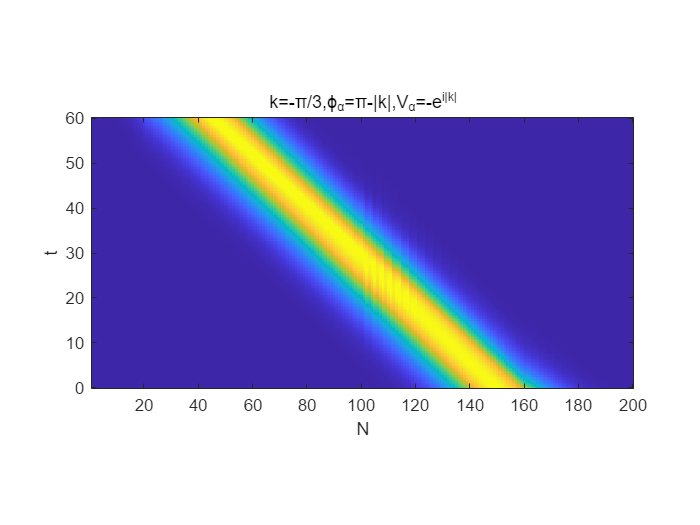

clim=[0 max(abs(psi0).^2)];
plotpsi2d(psi1(:,1:N), t1, N, clim)
pbaspect([2 1 1])
title('k=-\pi/3,\phi_\alpha=\pi-|k|,V_\alpha=-e^{i|k|}')

%两个侧耦合粒子
%构建哈密顿量
H0 = zeros(N+2, N+2);
for ii = 1:(N-1)
    H0 = interaction(H0, ii, ii+1, -J);
    H0(ii,ii) = wc;
end
H0(N, N) = wc;
if loop == true
    H0 = interaction(H0, N, 1, -J);
end

%在两端加上轻微的衰减，防止反射
%衰减不能太强，否则会直接反射
for ii = 1:20
    H0(ii,ii) = H0(ii,ii) - 0.1*J*1i;
end
for ii = (N-40):N
    H0(ii,ii) = H0(ii,ii) - 0.05*J*1i;
end

H = H0;
k = pi/3;
backward = false;

if backward
    Nc = Na + 50;
    k = -abs(k);
else
    Nc = Na - 50;
end
Va = -exp(-1i*abs(k));
Vb = -exp(1i*abs(k));
V0 = -2i*sin(abs(k));
phi_alpha = pi + abs(k);
phi_beta = pi + abs(k);

H = interaction(H, Na-1, N+1,-J);
H = interaction(H, Na, N+1, -J*exp(1i*phi_alpha));
H = interaction(H, Na+1, N+2,-J);
H = interaction(H, Na, N+2, -J*exp(1i*phi_beta));
H(N+1, N+1) = wc + Va;
H(N+2, N+2) = wc + Vb;
H(Na, Na) = wc + V0;

[VEC, D] = eig(H);

psi0 = [GaussianState(N, Nc, k, 16.65);0;0];
tmax = 60;
tic
[t1, psi1] = psicalc(H, psi0, tmax, 'eig', 180, VEC, D);
toc

历时 0.298878 秒。


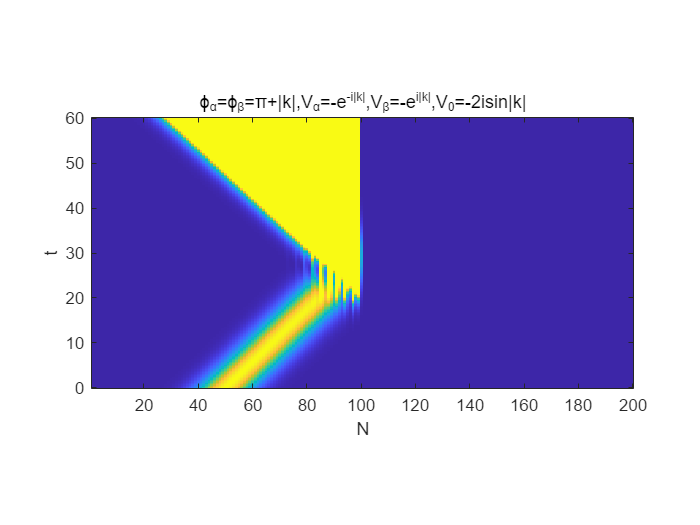

clim=[0 max(abs(psi0).^2)];
plotpsi2d(psi1(:,1:N), t1, N, clim)
pbaspect([2 1 1])
title('\phi_\alpha=\phi_\beta=\pi+|k|,V_\alpha=-e^{-i|k|},V_\beta=-e^{i|k|},V_0=-2isin|k|')

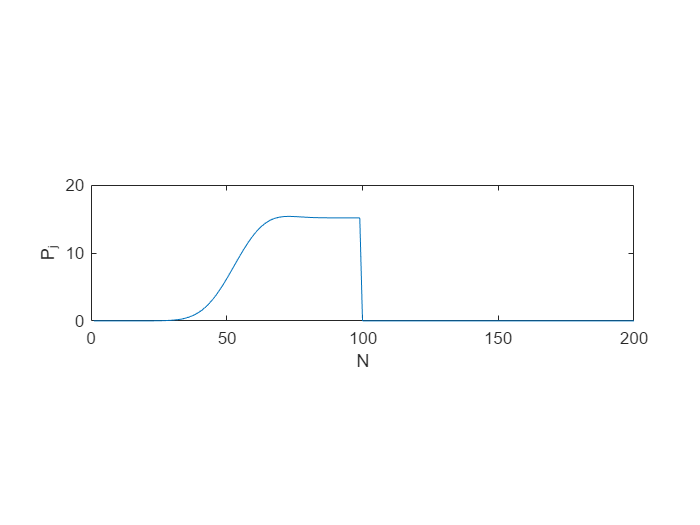

plot(1:N,abs(psi1(end,1:N)).^2)
pbaspect([4 1 1])
xlabel('N')
ylabel('P_j')
ylim([0,20])